# Implementing Gemm with different loop orderings

This Live Script helps you visualize the performance of the implementations of Gemm with different loop orderings 

To gather the performance data, execute 

clear

system('make test_GemmAll')

echo "5 32 1000 32" | ./driver_GemmAll.x > output_data_GemmAll.m


ans = 0

When completed, this creates output file 'output_data_GemmAll.m' with timing data.  This Life Script then creates graphs from that timing data.

## Step 1a: Load timing data

output_data_GemmAll

## Step 1b: Make sure you are getting the right answer

In output_data_GemmAll.m, for each execution of GemmXXX, timing data is collected as well as how close the answer is to the answer attained by the reference implementation.  Here we look at the maximum difference over all experiments.  This should be somewhere on the order of $ 10^{-11} $ or smaller.  Notice that you can expect some difference between the two implementations, due to round-off error and the order in which computations are performed.

MaxAbsDiff = max( abs( data_GemmIJP( :, 3 ) ) )

MaxAbsDiff = 0

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine


MaxAbsDiff = max( abs( data_GemmJIP( :, 3 ) ) )

MaxAbsDiff = 0

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine



MaxAbsDiff = max( abs( data_GemmIPJ( :, 3 ) ) )

MaxAbsDiff = 0

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine



MaxAbsDiff = max( abs( data_GemmPIJ( :, 3 ) ) )

MaxAbsDiff = 0

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine



MaxAbsDiff = max( abs( data_GemmJPI( :, 3 ) ) )

MaxAbsDiff = 0

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine



MaxAbsDiff = max( abs( data_GemmPJI( :, 3 ) ) )

MaxAbsDiff = 0

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine


## Step 1c: Plot the timing data.

The first graph shows the execution time of the different implementations as a function of the matrix size $n$.

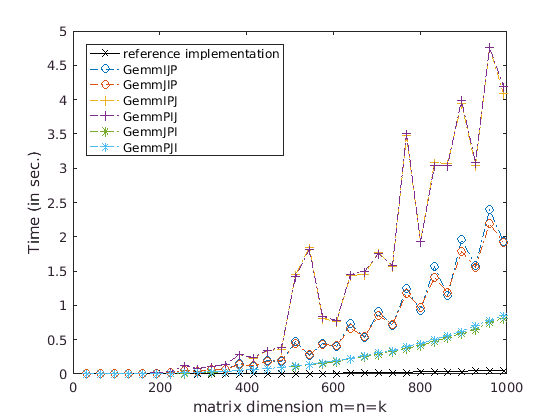

close all

% Plot the reference implementation performance
plot( data_ref( :,1 ), data_ref( :, 2 ), 'k-x' ); 

hold all    % Plot additional data in same figure

plot( data_GemmIJP( :,1 ), data_GemmIJP( :, 2 ), '-.o' ); 
plot( data_GemmJIP( :,1 ), data_GemmJIP( :, 2 ), '-.o' ); 

plot( data_GemmIPJ( :,1 ), data_GemmIPJ( :, 2 ), '-.+' ); 
plot( data_GemmPIJ( :,1 ), data_GemmPIJ( :, 2 ), '-.+' ); 

plot( data_GemmJPI( :,1 ), data_GemmJPI( :, 2 ), '-.*' ); 
plot( data_GemmPJI( :,1 ), data_GemmPJI( :, 2 ), '-.*' ); 

hold off   % Stop plotting additional data in same figure% Plot additional data in same figure

% Add x- and y-axis labels and legend
xlabel( 'matrix dimension m=n=k' );
ylabel( 'Time (in sec.)' );
legend( 'reference implementation', ...
        'GemmIJP', ...
        'GemmJIP', ...
        'GemmIPJ', ...
        'GemmPIJ', ...
        'GemmJPI', ...
        'GemmPJI', ...
        'Location', 'NorthWest' );

% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

Notice that the reference implementationis considerably faster than all the loop orderings of the simple "triple loop" in GemmXXX.c.  We illustrate that by plotting the speedup of the highly optimized reference implementation relative to GemmXXX.

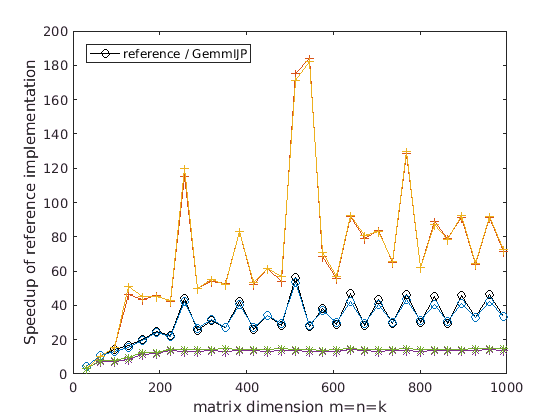

plot( data_ref( :,1 ), data_GemmIJP( :, 2 ) ./ data_ref( :, 2 ), 'k-o' ); 

hold all    % Plot additional data in same figure

plot( data_ref( :,1 ), data_GemmJIP( :, 2 ) ./ data_ref( :, 2 ), '-o' ); 
plot( data_ref( :,1 ), data_GemmIPJ( :, 2 ) ./ data_ref( :, 2 ), '-+' ); 
plot( data_ref( :,1 ), data_GemmPIJ( :, 2 ) ./ data_ref( :, 2 ), '-+' ); 
plot( data_ref( :,1 ), data_GemmJPI( :, 2 ) ./ data_ref( :, 2 ), '-*' ); 
plot( data_ref( :,1 ), data_GemmPJI( :, 2 ) ./ data_ref( :, 2 ), '-*' ); 

hold off   % Stop plotting additional data in same figure% Plot additional data in same figure

% Add x- and y-axis labels and legend
xlabel( 'matrix dimension m=n=k' );
ylabel( 'Speedup of reference implementation' );
legend( 'reference / GemmIJP', ...
        'reference / GemmJIP', ...
        'reference / GemmIPJ', ...
        'reference / GemmPIJ', ...
        'reference / GemmJPI', ...
        'reference / GemmPJI', ...
        'Location', 'NorthWest' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

## Step 3: Plot performance.

We often view the rate at which routines compute rather than the time required for completing the computation.

When all matrices are $n \times n$, we know that a matrix-matrix  multiplication$ A B + C$ requires $2n^3$ floating point operations (flops).  This means that the number of operations performed per second is given by ${2 n^3}/{t}$ flops, where $t$ is the time, in seconds, for computing the multiplication.  Now, a typical current core can perform billions of flops per second, so instead we report performance in GFLOPS/sec. (billions of flops per second): ${2 n^3}/{t} \times 10^{-9}$.

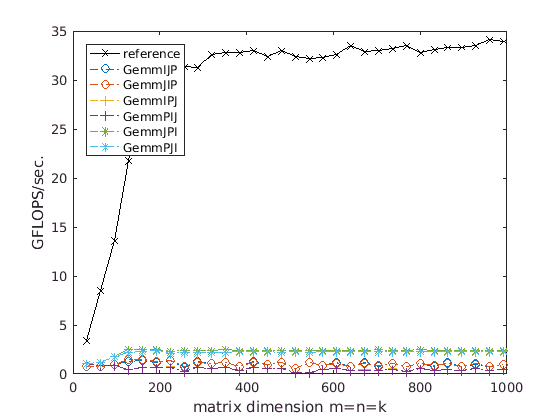

ns = data_ref( :, 1 );                                   % Extract a vector of matrix size.
gflops = 2.0 * ns.^3 ./ data_ref( :, 2 ) * 1.0e-9;    % Compute a vector of corresponding 
                                                           % GFLOPS/sec from the timing data.
plot( ns, gflops, 'k-x' );                                      % Plot the performance data

hold all

ns = data_GemmIJP( :, 1 );
gflops = 2.0 * ns.^3 ./ data_GemmIJP( :, 2 ) * 1.0e-9;
plot( ns, gflops, '-.o' ); 

ns = data_GemmJIP( :, 1 );
gflops = 2.0 * ns.^3 ./ data_GemmJIP( :, 2 ) * 1.0e-9;
plot( ns, gflops, '-.o' ); 

ns = data_GemmIPJ( :, 1 );
gflops = 2.0 * ns.^3 ./ data_GemmIPJ( :, 2 ) * 1.0e-9;
plot( ns, gflops, '-.+' ); 

ns = data_GemmPIJ( :, 1 );
gflops = 2.0 * ns.^3 ./ data_GemmPIJ( :, 2 ) * 1.0e-9;
plot( ns, gflops, '-.+' );

ns = data_GemmJPI( :, 1 );
gflops = 2.0 * ns.^3 ./ data_GemmJPI( :, 2 ) * 1.0e-9;
plot( ns, gflops, '-.*' ); 

ns = data_GemmPJI( :, 1 );
gflops = 2.0 * ns.^3 ./ data_GemmPJI( :, 2 ) * 1.0e-9;
plot( ns, gflops, '-.*' ); 

xlabel( 'matrix dimension m=n=k' );
ylabel( 'GFLOPS/sec.' );
legend( 'reference', ...
        'GemmIJP', ...
        'GemmJIP', ...
        'GemmIPJ', ...
        'GemmPIJ', ...
        'GemmJPI', ...
        'GemmPJI', ...
        'Location', 'NorthWest' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

## Conclusion

By reordering the loops of the we can slightly improve the peformance of the GEMM implementation. Can you reason through why some loop orderings perform better than the others?